# EE115 Lab 5

# Buddy Ugwumba

clf
% In order to ignore the step function, t>0
t = 1:0.001:20;
% First condition: K>0
K_1 = linspace(1,5,4)

K_1 =     1.0000    2.3333    3.6667    5.0000


% Second condition: a>K/4
a_1 = 2

a_1 = 2

k_f = 0.5;
% In this equation, the constation and condition control the magnitude
% The sine function controls the oscillation
% The exponential function determines the overal shape of the graph
for i = 1:length(K_1)
    condition = sqrt((4*K_1(i)*a_1) - (K_1(i)^2));
    e = exp((-1/2)*K_1(i).*t);
    constant = 4*pi*k_f;
    theta_e_t = (constant./condition).*e.*sin(condition.*t);
    hold on
    text = ['K = ', num2str(K_1(i))];
    plot(t, theta_e_t,'DisplayName',text)
    fig1_info = stepinfo(theta_e_t,t)
end

fig1_info = struct with fields:
        RiseTime: 0.1493
    SettlingTime: 9.1447
     SettlingMin: -0.9921
     SettlingMax: 0.5479
       Overshoot: 1.3453e+06
      Undershoot: 1.9478e+06
            Peak: 0.9921
        PeakTime: 1.7110


fig1_info = struct with fields:
        RiseTime: 0.2070
    SettlingTime: 4.1476
     SettlingMin: -0.0534
     SettlingMax: 0.1463
       Overshoot: 6.9907e+11
      Undershoot: 2.5513e+11
            Peak: 0.4008
        PeakTime: 1.2110


fig1_info = struct with fields:
        RiseTime: 0.3145
    SettlingTime: 2.9887
     SettlingMin: -0.0187
     SettlingMax: 0.0471
       Overshoot: 1.1508e+17
      Undershoot: 2.7131e+16
            Peak: 0.1999
        PeakTime: 1.0740


fig1_info = struct with fields:
        RiseTime: 0.3498
    SettlingTime: 2.3293
     SettlingMin: -0.0089
     SettlingMax: 0.0124
       Overshoot: 4.4931e+21
      Undershoot: 3.4139e+22
            Peak: 0.0942
        PeakTime: 1.0690


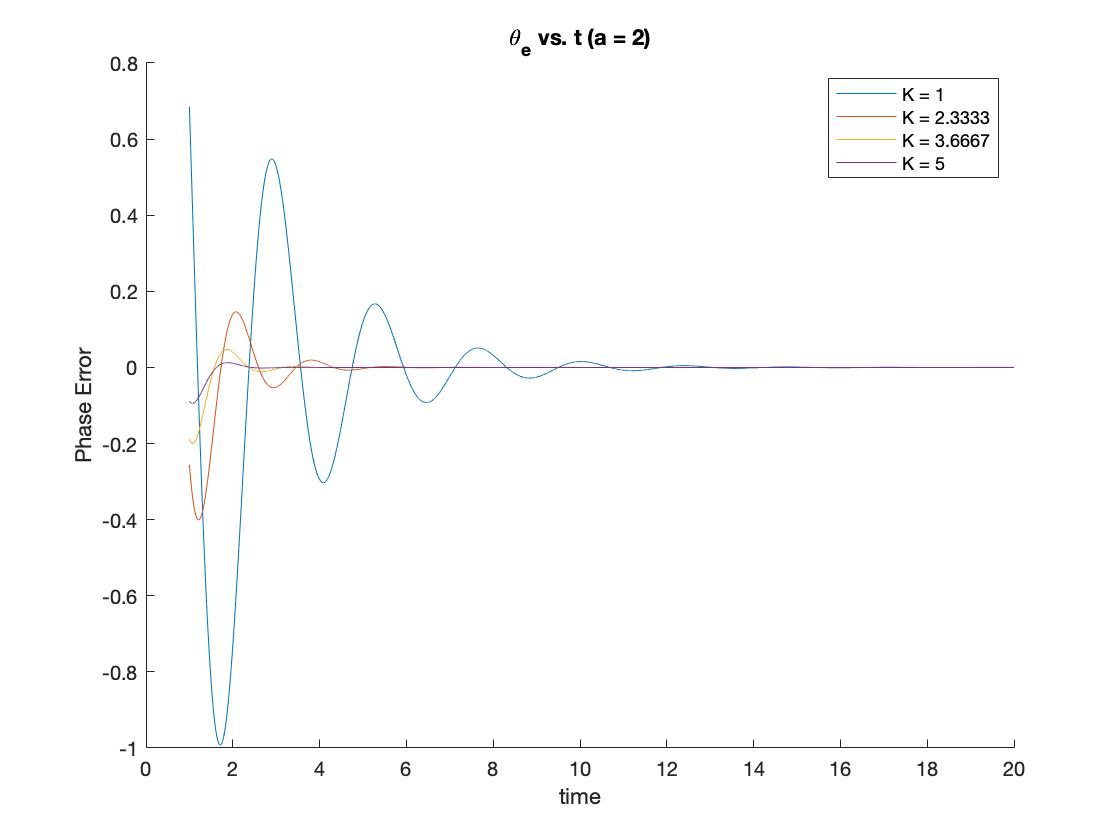

hold off
legend show
title('\theta_e vs. t (a = 2)')
xlabel('time')
ylabel('Phase Error')

clf
t = 1:0.001:15;
K_2 = 1

K_2 = 1

a_2 = linspace(2,6,4)

a_2 =     2.0000    3.3333    4.6667    6.0000


for i = 1:length(a_2)
    condition = sqrt((4*K_2.*a_2(i)) - (K_2^2));
    e = exp((-1/2)*K_2.*t);
    constant = 4*pi*k_f;
    theta_e_t = (constant/condition).*e.*sin(condition.*t);
    hold on
    text = ['a = ', num2str(a_2(i))];
    plot(t, theta_e_t,'DisplayName',text)
    fig2_info = stepinfo(theta_e_t,t)
end

fig2_info = struct with fields:
        RiseTime: 0.1491
    SettlingTime: 9.1675
     SettlingMin: -0.9921
     SettlingMax: 0.5479
       Overshoot: 5.6949e+04
      Undershoot: 8.2592e+04
            Peak: 0.9921
        PeakTime: 1.7110


fig2_info = struct with fields:
        RiseTime: 0.1186
    SettlingTime: 8.6952
     SettlingMin: -0.3777
     SettlingMax: 0.5907
       Overshoot: 8.9541e+04
      Undershoot: 1.4020e+05
            Peak: 0.9240
        PeakTime: 1.3020


fig2_info = struct with fields:
        RiseTime: 0.2320
    SettlingTime: 8.7100
     SettlingMin: -0.4070
     SettlingMax: 0.5914
       Overshoot: 3.3405e+05
      Undershoot: 4.8556e+05
            Peak: 0.8594
        PeakTime: 1.0930


fig2_info = struct with fields:
        RiseTime: 0.2227
    SettlingTime: 8.8558
     SettlingMin: -0.4186
     SettlingMax: 0.5808
       Overshoot: 2.5537e+05
      Undershoot: 3.4829e+05
            Peak: 0.7919
        PeakTime: 1


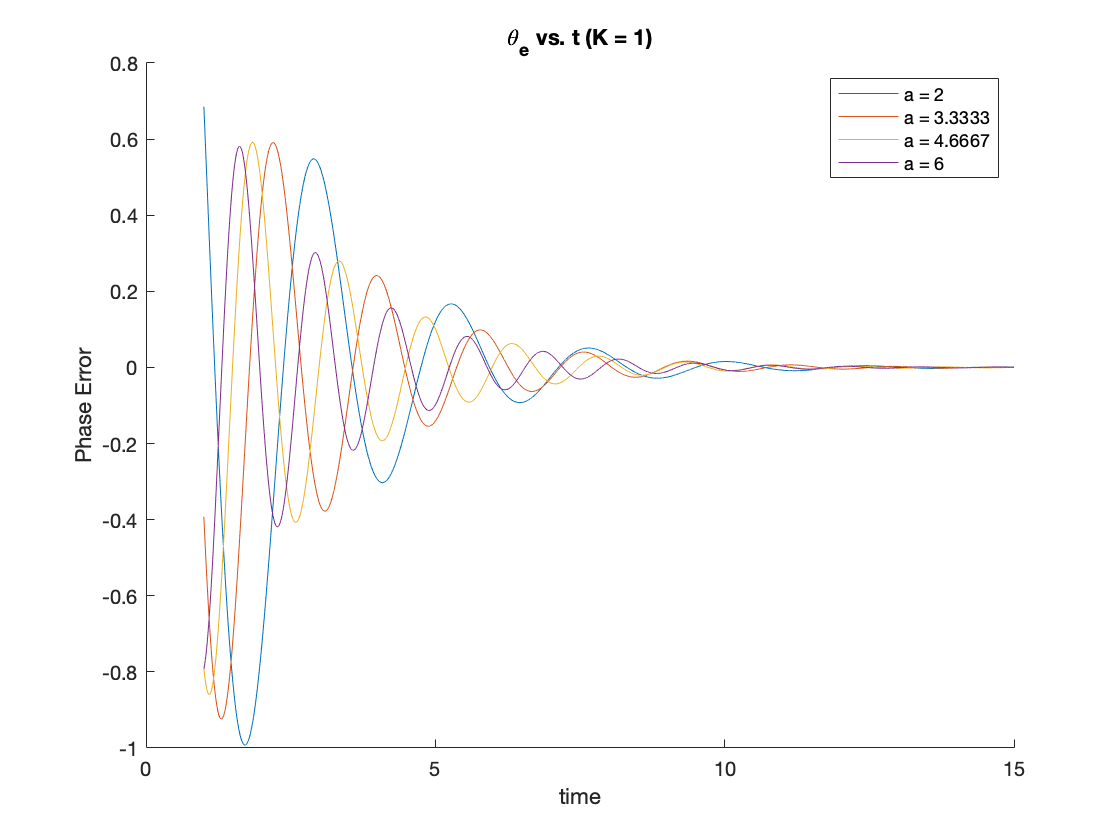

hold off
legend show
hold off
legend show
title('\theta_e vs. t (K = 1)')
xlabel('time')
ylabel('Phase Error')

Analysis:

When we compare both graphs, we see that the value K effects the peak of the graph. The higher the value of K the lower the magnitude. If K becomes too large, with respect to a fixed a, the magnitude becomes complex because of the $K^2$ value. When the magnitude becomes complex, the shape of the error function reverses. K also deteremines the speed at which the error function converges. Looking at the exponential function in 7, $e^{-\frac{1}{2}\mathrm{Kt}}$ we see that the parameter K also determines the speed at which the function converges.  Concerning an exponential function in this form, the larger the argument the quicker the exponential goes to 0 with respect to time. The value of a on the other hand is responsible for the oscialltion. The a value determines the oscillation or frequency.  Looking at the sine argument in 7 we can define the equation for frequency as $2\pi f=\sqrt{4\mathrm{Ka}=K^2 \to f=\frac{\sqrt{4\mathrm{ka}-K^2 }}{2\eta }}$. Thus, if we fix K and incrrease the value of a the frequency increases because the numerator increases.  